# Runge's Phenomenon: When Neither LSF nor Interpolation Succeed...

## Runge's Phenomenon. An Example

Consider the function:


$$$$
f(x) = \frac{1}{1+ 25 x^{2}},
$$$$


a sample of N+1, with $N=10$ of equispaced nodes $x_{i} = -1+0.2(i-1)$ in the interval $I = [-1,1]$, and the values of the functon at those points,$f(x_{i})$, $i=1,2,\dots,N$+1. 

## LSF Polynomials

For the above example, find the lsf polynomials corresponding to the degrees $3$, $5$, $7$, and $10$. 

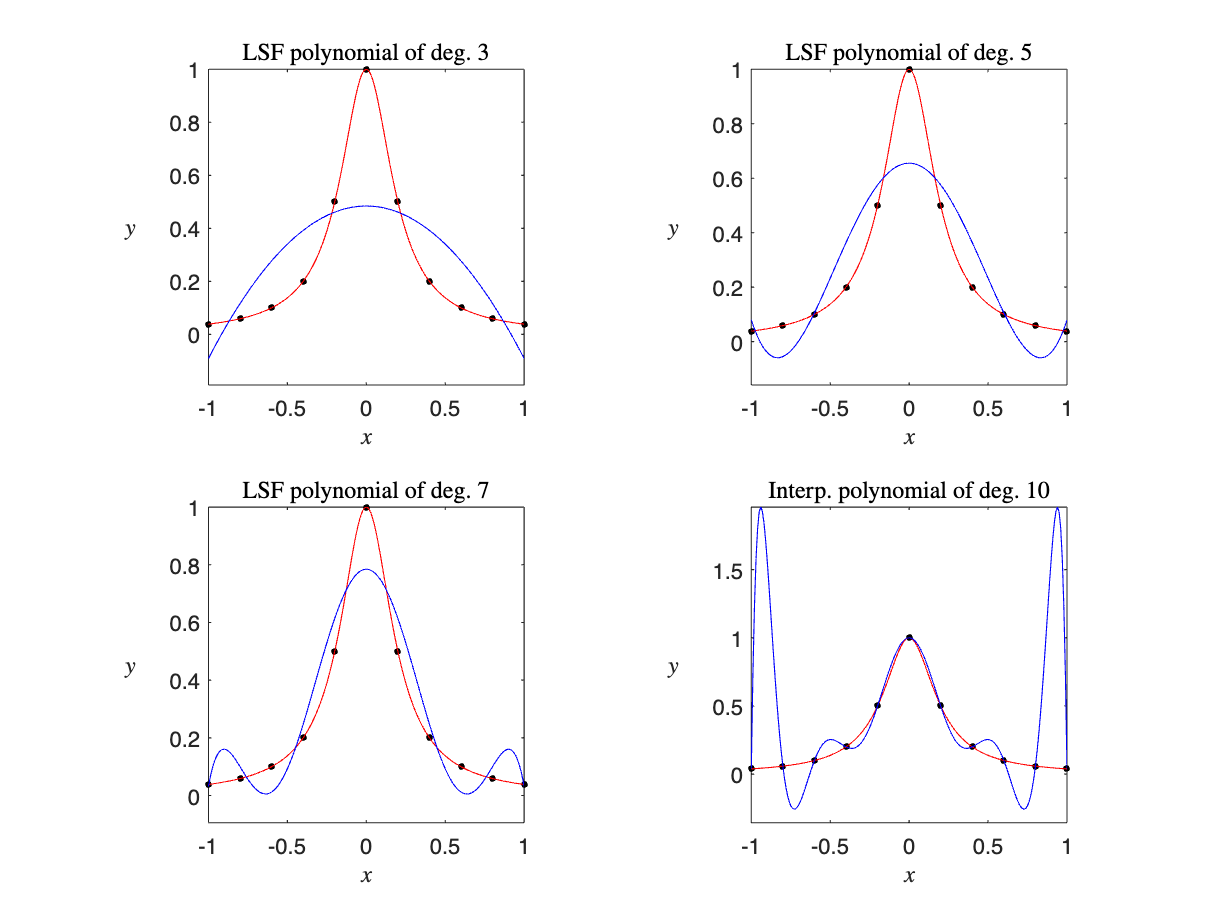

clearvars
close all

format short e
format compact

a = 1.0; b = -1.0; N = 10; M = 200;
f = @(x) 1./(1+25*x.^2);

xN = linspace(a,b,N+1); fN = f(xN);
xM = linspace(a,b,M+1); M1 = length(xM); fM = f(xM);

degrees = [3; 5; 7; 10]; sz = length(degrees);
meanErr = zeros(sz,1);
maxErr = zeros(sz,1);

figure()
set(gcf,'defaultTextInterpreter','LaTeX')
for k = 1:sz
    pn = polyfit(xN,fN,degrees(k));
    pM = polyval(pn,xM);
    subplot(2,2,k);
    plot(xN,fN,'o',...
        'Marker','o',...
        'MarkerFaceColor','black',...
        'MarkerEdgeColor',...
        'black',...
        'MarkerSize', 2, ...
        'lineWidth',1)
    hold on
    plot(xM,fM,'-','color','red')
    plot(xM,pM,'-','color','blue')
    xlabel('$x$')
    ylabel('$y\quad$','rot',360)
    if degrees(k) < N
        title(['LSF polynomial of deg. ', num2str(degrees(k))],...
            'interpreter','LaTeX')
    else
        title(['Interp. polynomial of deg. ', num2str(degrees(k))],...
            'interpreter','LaTeX')
    end
    ymax = max([fM,pM]);
    ymin = min([fM,pM])-0.1;
    pbaspect([1,1,1]);
    axis([-1,1,ymin,ymax])
    hold off
    % Compute the errors
    meanErr(k) = norm(fM-pM,1)/M1;
    maxErr(k) = norm(fM-pM,Inf);
end

### Errors in the LSF

%Create a table
%Output using sprintf:
t1 = sprintf('%4s%11s%11s\n', ...
    'DEG','MEAN.ERR','MAX.ERR');
t2 = sprintf('%4d%12.4e%12.4e\n',[degrees, meanErr, maxErr]'); 
disp([t1 t2])

 DEG   MEAN.ERR    MAX.ERR
   3  1.5835e-01  5.1588e-01
   5  1.1186e-01  3.4478e-01
   7  7.9675e-02  2.1539e-01
  10  2.8987e-01  1.9156e+00



%Output as a Matlab table:
errLSF = table('Size',[sz, 3],'VariableTypes',...
     {'uint8','double','double'},...
     'VariableNames',{'Degree','Mean Err.','Max. Err.'}); %Matlab > 2007 to work

errLSF.Degree = degrees;
errLSF.('Mean Err.') = meanErr;
errLSF.('Max. Err.') = maxErr;
errLSF

errLSF = 4×3 table
      Degree      Mean Err.     Max. Err. 
    __________    __________    __________
    3.0000e+00    1.5835e-01    5.1588e-01
    5.0000e+00    1.1186e-01    3.4478e-01
    7.0000e+00    7.9675e-02    2.1539e-01
    1.0000e+01    2.8987e-01    1.9156e+00

## Splines

### Linar Splines (polygonal approximation)

figure()
set(gcf,'defaultTextInterpreter','LaTeX')
lM = interp1(xN,fN,xM);
subplot(1,2,1)
plot(xN,fN,'o',...
        'Marker','o',...
        'MarkerFaceColor','black',...
        'MarkerEdgeColor',...
        'black',...
        'MarkerSize', 2, ...
        'lineWidth',1)
title('1D Linear spline approximation')
hold on
plot(xM,fM,'-','color','red')
plot(xM,lM,"LineStyle",'-','color','blue')
xlabel('$x$')
ylabel('$y\quad$','rot', 360)
ymax = max([fM,lM]);
ymin = min([fM,lM])-0.1;
pbaspect([1 1 1])
axis([-1,1,ymin,ymax])
hold off

### Cubic Splines

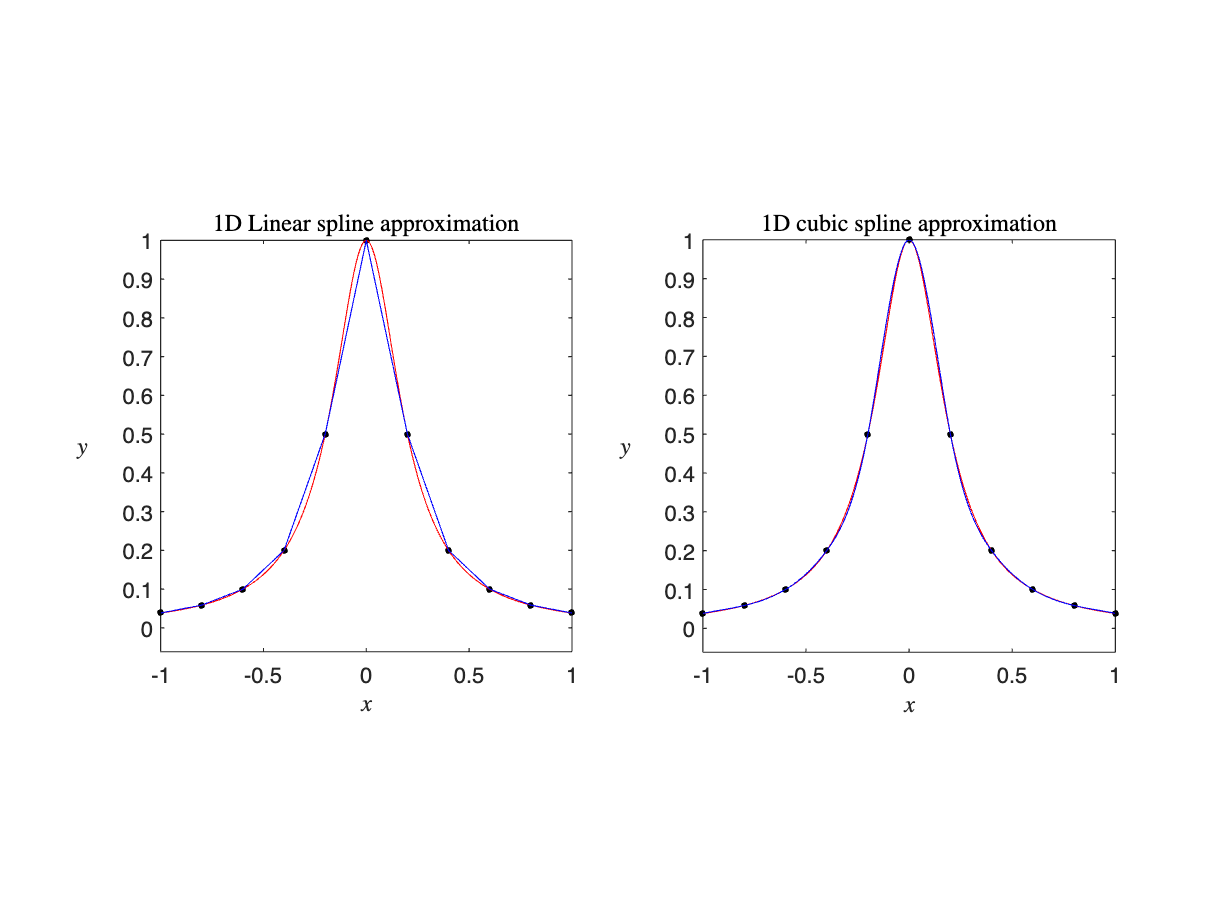

sM = spline(xN,fN,xM);
subplot(1,2,2)
plot(xN,fN,'o',...
        'Marker','o',...
        'MarkerFaceColor','black',...
        'MarkerEdgeColor',...
        'black',...
        'MarkerSize', 2, ...
        'lineWidth',1)
title('1D cubic spline approximation')
hold on
plot(xM,fM,'-','color','red')
plot(xM,sM,"LineStyle",'-','color','blue')
xlabel('$x$')
ylabel('$y\quad$','rot', 360)
ymax = max([fM,sM]);
ymin = min([fM,sM])-0.1;
pbaspect([1 1 1])
axis([-1,1,ymin,ymax])
hold off

### Errors in spline approximation

%Create a table
MeanErr = [norm(fM-lM,1)/M1; norm(fM-sM)/M1];
MaxErr = [norm(fM-lM,Inf); norm(fM-sM,Inf)];

ErrSplines = array2table([MeanErr, MaxErr],...
    'VariableNames',{'Mean Err.','Max. Err.'},...
    'RowNames',{'Linear Spline';'Cubic Spline'});

%ErrSplines = table(ErrSplines,'VariableNames',{'Mean and Max Errors'}); % Nested table

display(ErrSplines)

ErrSplines = 2×2 table
                     Mean Err.     Max. Err. 
                     __________    __________
    Linear Spline    1.4974e-02    6.7431e-02
    Cubic Spline     5.0490e-04    2.1960e-02